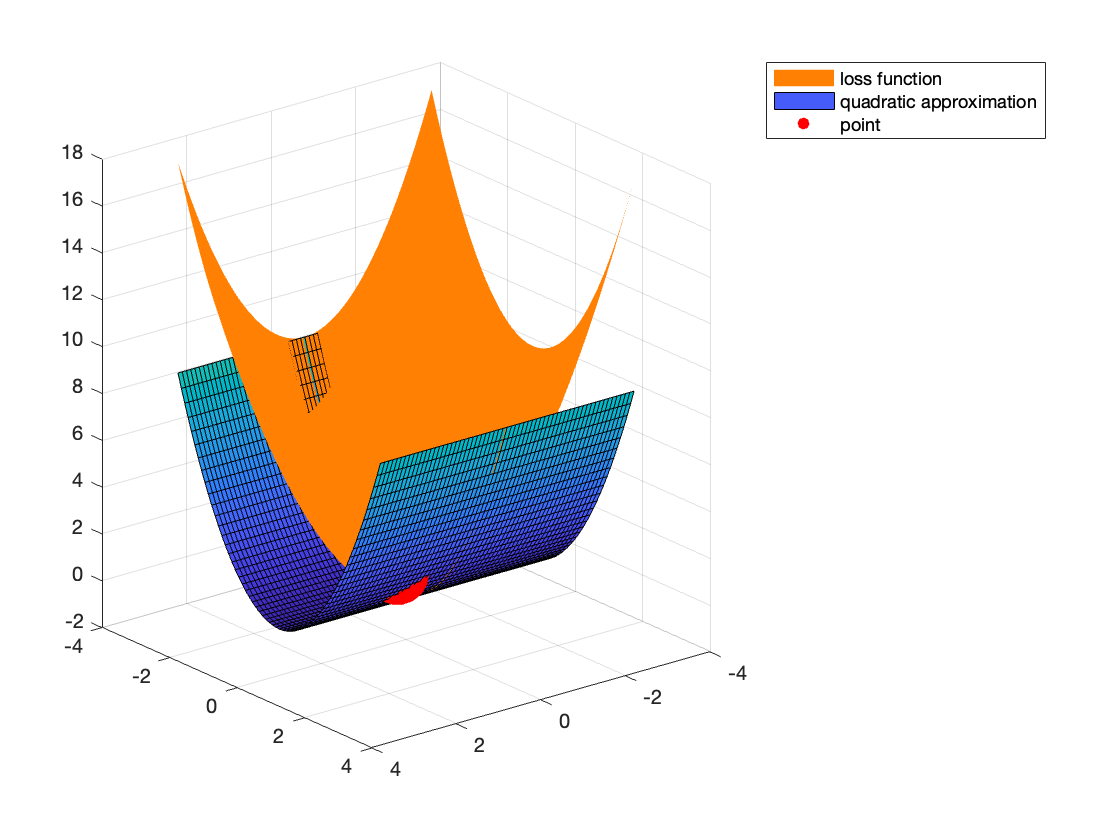

close all
clear
x0 = [1;1];
x = -3:1e-1:3;
y = x;
[X,Y] = meshgrid(x);

% plot loss function 
s1 = surf(X, Y, func(X, Y));
s1.FaceColor = [1,0.5,0.01];
s1.LineStyle = "none";
hold on
% plot quadratic approximation
surf(X,Y,approximation(0, 0, X, Y));
s3 = scatter3(1,1,func(1,1), 'filled', "MarkerFaceColor",[1,0,0]);
s3.SizeData = 1000;
legend('loss function', 'quadratic approximation', 'point')
hold off

view([141.4 18.2])

% surf(X,Y, x0(1), x0(2), )


function f = func(x, y)
% loss function
    f = x.^2+y.^2;
end

function g = gradient(x, y)
% gradient function
    g1 = 2.*x;;
    g2 = 2.*y;
    g = [g1;g2];
end

function h = hessian(x, y)
% hessian function
    h11 = 2;;
    h12 = 0;
    h21 = 0;
    h22 = 2;
    h = [h11 h12;h21 h22];
end

function f1 = approximation(x0, y0, deltax, deltay)
% Taylor expansion function 
    g = gradient(x0, y0);
    g1 = g(1);
    g2 = g(2);
    h = hessian(x0, y0);
    h11 = h(1,1);
    h12 = h(1,2);
    h21 = h12;
    h22 = h(2,2);
    f1 = func(x0, y0) + g1.*(deltax-x0)+g2.*(deltay-y0)  + ...
        1./2.* (((deltax-x0).*h11 + (deltay-y0).*h21) * (deltax-x0) + ...
        ((deltax-x0).*h12+(deltay-y0).*h22).*(deltay-y0));
end